# Forward Kinematics

In the previous section, we saw what DH Parameters are, and how they can transform any coordinate system into any other based on the configuration of the joints.

In this section, we'll use the same knowledge to do the **Forward Kinematics of a Robot**, i.e. specify the joint angles and see where the end effector is.

We are going to repeat the exact steps as in the second script, except this time, we will specify our own DH Parameters and Joint Angles to control the Robot.

First, let us define the link lengths. These stay fixed.

a1 = 0    ; d1 = 0.2  ; alpha1 =  pi/2;
a2 = 0.2  ; d2 = 0    ; alpha2 =     0;
a3 = 0.1  ; d3 = 0    ; alpha3 =     0;
a4 = 0    ; d4 = 0    ; alpha4 =  pi/2;
a5 = 0    ; d5 = 0    ; alpha5 =  pi/2;
a6 = 0    ; d6 = 0.1  ; alpha6 =  0   ;

Next, let us set the angles (Thetas) in degrees. We will convert these to radians later

th1d = 10; th1 = deg2rad(th1d);
th2d = 25; th2 = deg2rad(th2d);
th3d = -30; th3 = deg2rad(th3d);
th4d = 0; th4 = deg2rad(th4d);
th5d = 0; th5 = deg2rad(th5d) + pi/2; % for straightening
th6d = 0; th6 = deg2rad(th6d);

## Now working out Joints and End-Effector Coordinates using Forward Kinematics

T01 = dh_param(a1,d1,alpha1,th1); 
T12 = dh_param(a2,d2,alpha2,th2);
T23 = dh_param(a3,d3,alpha3,th3);
T34 = dh_param(a4,d4,alpha4,th4);
T45 = dh_param(a5,d5,alpha5,th5);
T56 = dh_param(a6,d6,alpha6,th6);

O1  = T01(1:3,end); % (x,y,z)
T02 = T01*T12; O2  = T02(1:3,end); % (x,y,z)
T03 = T02*T23; O3  = T03(1:3,end); % (x,y,z)
T04 = T03*T34; O4  = T04(1:3,end); % (x,y,z)
T05 = T04*T45; O5  = T05(1:3,end); % (x,y,z)
T06 = T05*T56; O6  = T06(1:3,end) % (x,y,z)

O6 =     0.3747
    0.0661
    0.2671


## Visualization

That is sufficient for calculation. However we can also plot the links for visualisation.

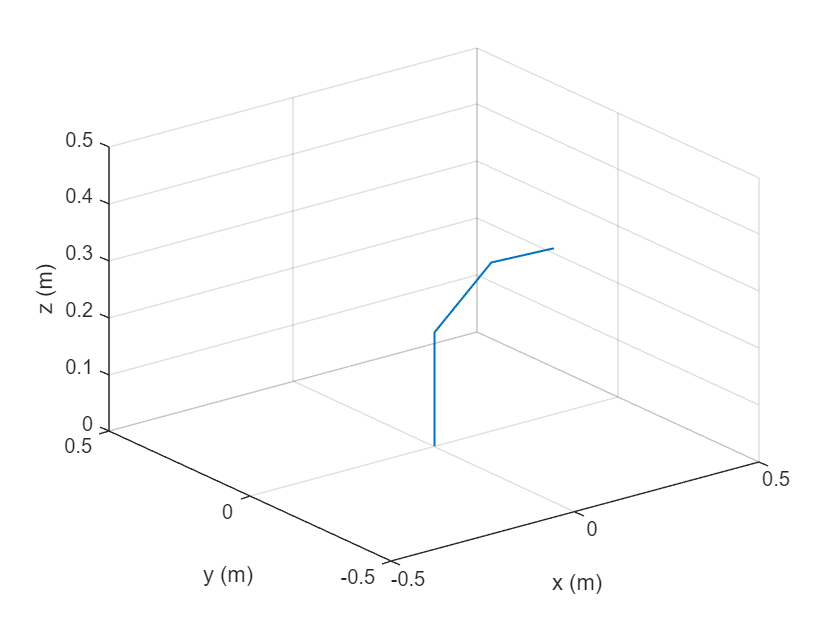

X = [0 O1(1) O2(1) O3(1) O4(1) O5(1) O6(1)];
Y = [0 O1(2) O2(2) O3(2) O4(2) O5(2) O6(2)];
Z = [0 O1(3) O2(3) O3(3) O4(3) O5(3) O6(3)];

plot3(X,Y,Z,"LineWidth",1)
grid
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)')
xlim([-0.5 0.5]); ylim([-0.5 0.5]); zlim([0 0.5])

function T = dh_param(a,d,alpha,theta)
% This function generates a transformation matrix T
% depending on input dh parameters 
% theta, d, alpha and a

% calculating sin-cos for theta and alpha
St = sin(theta);
Ct = cos(theta);

Sa = sin(alpha);
Ca = cos(alpha);

% calculating matrix
T = [Ct -St*Ca St*Sa  a*Ct;...
     St Ct*Ca  -Ct*Sa a*St;...
     0  Sa     Ca     d   ;...
     0  0      0      1  ];

end
